% ir = randperm(1000)
ad = "cv/10c/id.mat";
% save(ad,"gn","-append") % ir
load(ad, 'c') % for tc
whos("-file",ad)

  Name      Size                  Bytes  Class     Attributes

  c         2x10                 140240  cell                
  cc        2x10                 812240  cell                
  g         2x10              207701600  cell                
  gn        2x2                24022200  cell                
  gs        2x2                24022200  cell                
  gt        2x2                24022200  cell                
  idx       1x10                     80  double              
  ir        1x1000                 8000  double              



## tc

load(ad, 'ir')
% for co = 1:10
%         tc{r,co} = c{r,idx(ci(co))};
%        end 
% t = table('Size',[2,10]);

## Nr

nrt = cell(2,2);
for r = 1:2
    nrt{r,1} = c{r,1};
    for k = 2:10
        nrt{r,1} = [nrt{r,1};
                   c{r,k}];
    end
    t = nrt{r,1}; nrt{r,1} = t(ir(1:700),:);
    nrt{r,2} = t(ir(701:end),:);
end
nrt

nrt = 2x2 cell array
    {700x6 table}    {300x6 table}
    {700x6 table}    {300x6 table}


## N10

tc = cell(2,2);
for r = 1:2
    tc{r,1} = c{r,1};
    for k = 2:10
        tc{r,1} = [tc{r,1};
                   c{r,k}];
    end
    t = tc{r,1}; tc{r,1} = t(ir(1:700),:);
    tc{r,2} = t(ir(701:end),:);
end
tc

tc = 2x2 cell array
    {700x6 table}    {300x6 table}
    {700x6 table}    {300x6 table}


nt = cell(2,2);
for r = 1:2
    nt{r,1} = c{r,1};
    for k = 2:10
        nt{r,1} = [nt{r,1};
                   c{r,k}];
    end
    t = nt{r,1};
    if r == 1
        n = t; sh = 60; % 70;
        kh = t(:, 1).Variables;
        ka = t(:, 2).Variables; snr = 55; % sh
        o = t(:, 3).Variables; so = snr+20; %-20+20
        n(:,1).Variables =awgn(kh,sh,'measured');
        % nt(:,1).Variables = ntla(:, 1).Variables;
        n(:,2).Variables=awgn(ka,snr,'measured');
        % nt(:,2).Variables = ntla(:, 2).Variables;
        n(:,3).Variables = awgn(o,so,'measured');
    end
    t(:,1:3).Variables = n(:, 1:3).Variables;
    nt{r,1} = t(ir(1:700),:);
    nt{r,2} = t(ir(701:end),:);
end
nt

nt = 2x2 cell array
    {700x6 table}    {300x6 table}
    {700x6 table}    {300x6 table}


# gpr !/10:

% rng('default')
gs = cell(2,2); tic
for r = 1:2
    gs{r,1} = fitrgp(tc{r,1}, ... % gprMdll1
    tc{r,1}.Properties.VariableNames{end},...
    'Sigma',.002);
    gs{r,2} = fitrgp(tc{r,1}, ... % gprMdll2
    tc{r,1}.Properties.VariableNames{end}, ...
    'KernelFunction', 'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002);
end
toc
gs

## Modelling precision N

co = 1; tc{1,co}.Ylatitude(:) = tc{1,...
co}.Ylatitude(:)*10;
tc{2,co}.Ylongitude(:) = tc{2,...
co}.Ylongitude(:)*10;

# Latitude gpr:

% rng('default')
gt = cell(2,2); tic
for r = 1:2
    gt{r,1} = fitrgp(tc{r,1}, ... % gprMdll1
    tc{r,1}.Properties.VariableNames{end},...
    'Sigma',.002);
    gt{r,2} = fitrgp(tc{r,1}, ... % gprMdll2
    tc{r,1}.Properties.VariableNames{end}, ...
    'KernelFunction', 'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002);
end
toc
gt

load(ad, 'gt') % /10

p = zeros(300,2,2);
for r = 1:2
    for co = 1:2
        t = tc{r,2};
        p(:,r, co) = predict(gt{r,co},t(:, 1: ...
            end-1).Variables);
    end
end

tr = 301; d1km = zeros(tr-1, 10); d2km = d1km;

## N/10

d = d1km;
for co = 1:2
    for i = 1:300
        [d(i, co), ~] = ...
            lldistkm(...
            [tc{1,2}.Ylatitude(i...
            ) tc{2,2}.Ylongitude(i...
            )], [p(i,1,co) p(i,2,co)]/10);
    end
end
d = d*1000; % m

## nt

co = 1; nt{1,co}.Ylatitude(:) = nt{1,...
co}.Ylatitude(:)*10;
nt{2,co}.Ylongitude(:) = nt{2,...
co}.Ylongitude(:)*10;

# gpr:

% c
gn = cell(2,2); tic
for r = 1:2
    gn{r,1} = fitrgp(nt{r,1}, ... % gprMdll1
    nt{r,1}.Properties.VariableNames{end},...
    'Sigma',.002);
    gn{r,2} = fitrgp(nt{r,1}, ... % gprMdll2
    nt{r,1}.Properties.VariableNames{end}, ...
    'KernelFunction', 'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002);
end
toc
gn

load(ad, 'gn')

pt = zeros(300,2,2);
for r = 1:2
    for co = 1:2
        t = nt{r,2};
        pt(:,r, co) = predict(gn{r,co},t(:, 1: ...
            end-1).Variables);
    end
end

## /10

for co = 1:2
    for i = 1:300
        [d1km(i, co), d2km(i, co)] = ...
            lldistkm(...
            [nt{1,2}.Ylatitude(i ...
            ) nt{2,2}.Ylongitude(i ...
            )], [pt(i,1,co) pt(i,2,co)]/10);
    end
end
d1km = d1km*1000;

load(ad, 'gs')

p = zeros(300,2,2);
for r = 1:2
    for co = 1:2
        t = nrt{r,2};
        p(:,r, co) = predict(gs{r,co},t(:, 1: ...
            end-1).Variables);
    end
end

## Normal

ndk = d1km;
for co = 1:2
    for i = 1:300
        [ndk(i, co), ~] = ...
            lldistkm([nrt{1,2}.Ylatitude(i...
            ) nrt{2,2}.Ylongitude(i...
            )], [p(i,1,co) p(i,2,co)]);
    end
end
ndk = ndk*1000;

## Without x/10

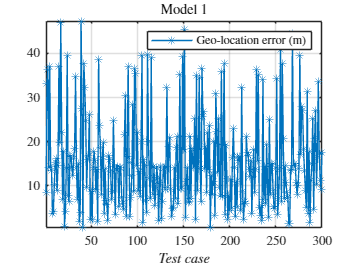

figure; plot(ndk(:, 1),'-*'); axis tight
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex'); axe(); grid on
% ylabel('Geo-location error (in meters)', ...
% 'interpreter','latex')
% print(fig,'DistG','-djpeg')
title('Model 1','interpreter','latex')

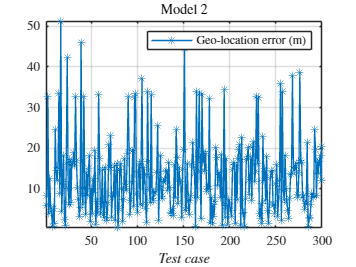

figure; plot(ndk(:, 2),'-*');
axis tight; axe(); grid on
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex')
% ylabel('Geo-location error (in meters)', ...
% 'interpreter','latex')
% print(fig,'DistG','-djpeg')
title('Model 2','interpreter','latex')

## No noise

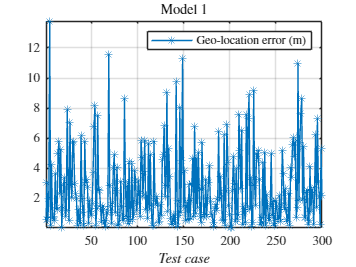

figure; plot(d(:, 1),'-*'); axis tight
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex'); axe(); grid on
% ylabel('Geo-location error (in meters)', ...
% 'interpreter','latex')
% print(fig,'DistG','-djpeg')
title('Model 1','interpreter','latex')

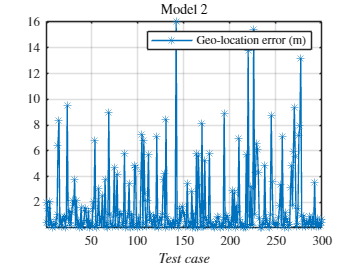

figure; plot(d(:, 2),'-*'); axis tight
% title('Model 1','interpreter','latex')
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex'); grid on; axe()
% ylabel('Geo-location error (in meters)', ...
% 'interpreter','latex')
% print(fig,'DistG','-djpeg')
title('Model 2','interpreter','latex')

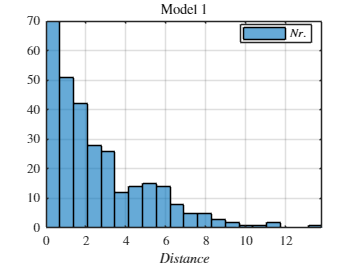

% print(fig,'Ca','-djpeg')
figure; histogram(d(:, 1),20)
title('Model 1','interpreter','latex')
xlabel('$Distance$','interpreter','latex'); axe()
legend({'$Nr.$'}, 'Location', 'Best', ...
'interpreter', 'latex'); axis tight; grid on

% title(['$SNR = $',num2str(so)], ...
% 'interpreter','latex')

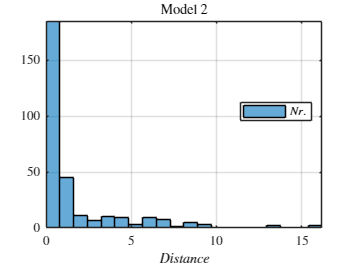

% print(fig,'Ca','-djpeg')
figure; histogram(d(:, 2),20)
title('Model 2','interpreter','latex')
xlabel('$Distance$','interpreter','latex'); axe()
grid on
legend({'$Nr.$'}, 'Location', 'Best', ...
'interpreter', 'latex');
% title(['$SNR = $',num2str(so)], ...
% 'interpreter','latex')
axis tight

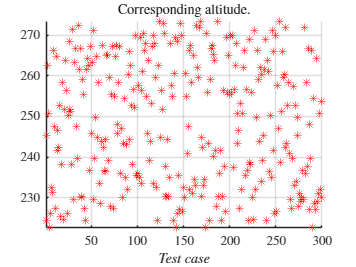

figure;
scatter(1:300, tc{1,2}.Altitude(:),'r*');
xlabel('$Test$ $case$','interpreter','latex');axe()
% ylabel('')
grid on; title('Corresponding altitude.', ...
'interpreter','latex'); axis tight

## Overall

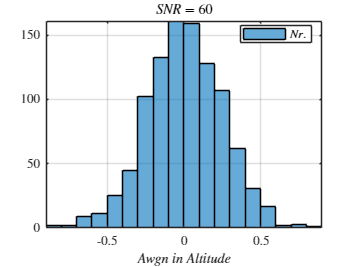

% sh = 60;
figure;
histogram(kh - n(:,1).Variables); axis tight
xlabel('\it Awgn in Altitude','interpreter', ...
    'latex'); grid on
legend({'$Nr.$'}, 'Location','Best', ...
    'interpreter','latex');
title(['$SNR = $',num2str(sh)], ...
    'interpreter','latex'); axe()

% '$\frac{d}{dx}sin(x)$';
% print(fig,'Ha','-djpeg')

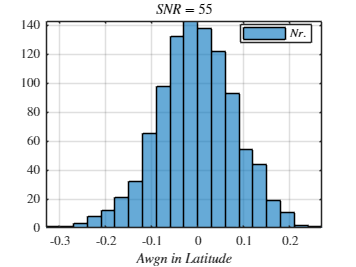

% snr = 60;
figure;
histogram(ka - n(:,2).Variables); axis tight
xlabel('\it Awgn in Latitude','interpreter', ...
    'latex'); grid on
legend({'$Nr.$'}, 'Location','Best', ...
    'interpreter','latex'); % 'northwest'
title(['$SNR = $',num2str(snr)], ...
    'interpreter','latex'); axe()

% print(fig,'Hla','-djpeg')

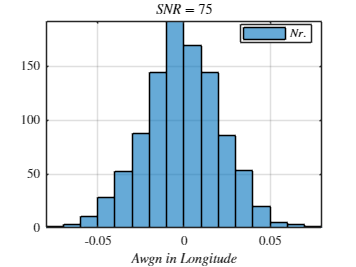

% so = snr+20;%-10;
figure;
histogram(o - n(:,3).Variables); axis tight
xlabel('\it Awgn in Longitude','interpreter', ...
    'latex'); grid on
legend({'$Nr.$'}, 'Location','Best', ...
    'interpreter', 'latex');
title(['$SNR = $',num2str(so)], ...
    'interpreter','latex'); axe()

% print(fig,'Ho','-djpeg')

fprintf(['Drone data, output: Latitude\n' ...
    '8 of ' num2str(length(n(:,1).Variables) ...
    ) ' rows, 3 of 6 cols']); n(1:8,:)

Drone data, output: Latitude
8 of 1000 rows, 3 of 6 cols

ans = 8x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylatitude
    ________    ________    _________    ______    ______    _________

     222.67      47.695      -122.13      236       190       47.643  
     224.89      47.581      -122.11      236       191       47.643  
     223.87      47.604      -122.12      236       191       47.643  
     224.95      47.581      -122.15      236       191       47.643  
     225.49      47.686      -122.14      236       192       47.643  
     225.76      47.572      -122.12      236       192       47.643  
     226.37      47.547      -122.14      236       192       47.643  
     227.13      47.684      -122.12      236       193       47.643  


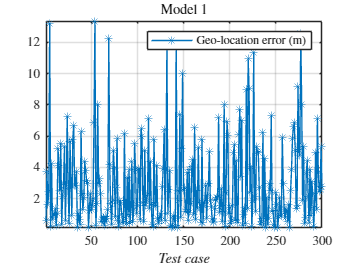

figure; plot(d1km(:, 1),'-*'); axis tight
title('Model 1','interpreter','latex')
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex'); grid on; axe()

% ylabel('Geo-location error (in meters)', ...
% 'interpreter','latex')
% print(fig,'DistG','-djpeg')

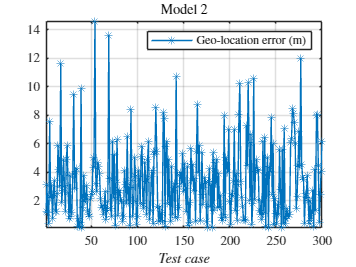

figure; plot(d1km(:, 2),'-*'); axis tight
title('Model 2','interpreter','latex')
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex'); axe(); grid on

% ylabel('Geo-location error (in meters)', ...
% 'interpreter','latex')
% print(fig,'DistG','-djpeg')

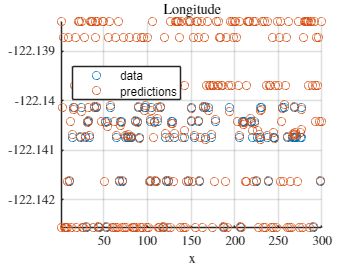

figure(); t = nt{2, 2}; scatter(1:300, t(:, ...
    end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight; xlabel('x','interpreter','latex');
% ylabel('y');
hold on;
scatter(1:300, pt(:,2,2)/10); hold off; grid on
legend({'data','predictions'}, ...
    'Location','Best');
title('Longitude','interpreter','latex'); axe()

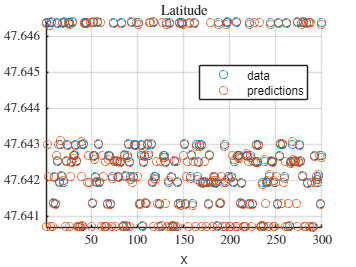

figure(); t = nt{1, 2}; scatter(1:300, t(:, ...
    end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight; xlabel('x');
% ylabel('y');
hold on;
scatter(1:300, pt(:,1,2)/10); hold off; grid on
legend({'data','predictions'}, ...
    'Location','Best');
title('Latitude','interpreter','latex'); axe()

[m, i] = min(d1km);
[M, I] = max(d1km); {m(1), M(1), m(2), M(2);
                     i(1), I(1), i(2), I(2)}'

ans = 4x2 cell array
    {[ 0.1261]}    {[ 35]}
    {[13.3737]}    {[ 54]}
    {[ 0.0669]}    {[242]}
    {[14.6186]}    {[ 54]}


% print(fig,'Ca','-djpeg')
figure; histogram(d1km(:, 1),20)
title('Model 1','interpreter','latex')
xlabel('$Distance$','interpreter','latex'); axe()
legend({'$Nr.$'}, 'Location', 'Best', ...
'interpreter', 'latex'); axis tight; grid on
% title(['$SNR = $',num2str(so)], ...
% 'interpreter','latex')

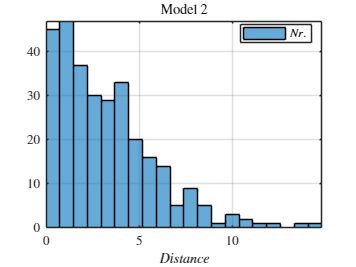

% print(fig,'Ca','-djpeg')
figure; histogram(d1km(:, 2),20)
title('Model 2','interpreter','latex')
xlabel('$Distance$','interpreter','latex'); axe()
grid on
legend({'$Nr.$'}, 'Location', 'Best', ...
'interpreter', 'latex');
% title(['$SNR = $',num2str(so)], ...
% 'interpreter','latex')
axis tight

## M2

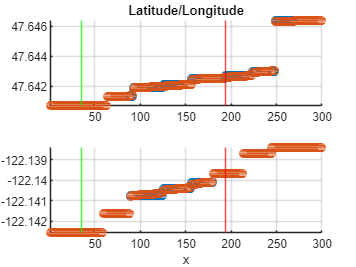

figure(); subplot(2,1,1); t = nt{1, 2};
scatter(1:300, sort(t(:, end).Variables));
% plot(tlts(:, ...
%     end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight; hold on; [s, in] = sort(pt(:,1,2)/10);
scatter(1:300, s); hold off;
grid on
% legend({'dataA','predA'}, ...
%     'Location','Best');
title('Latitude/Longitude');
m2 = [find(I(2)==in); find(i(2)==in)];
xline(m2(2), 'g'); xline(m2(1), 'r')

subplot(2,1,2);
 t = nt{2, 2}; scatter(1:300, sort(t(:, ...
    end).Variables)); axis tight; xlabel('x')
hold on;
scatter(1:300, sort(pt(:,2,2)/10)); hold off;
grid on
% legend({'dataL','predL'}, ...
%     'Location','Best');
xline(m2(2), 'g'); xline(m2(1), 'r')

function axe()
    axes = gca;
    axes.XAxis.TickLabelInterpreter = 'latex';
    axes.YAxis.TickLabelInterpreter = 'latex';
end